clc
clear all
close all
N_DOFS = 4;
link_length=0.4;
dh.theta=zeros(1,N_DOFS);
dh.alpha = zeros(1,N_DOFS);
dh.d = zeros(1,N_DOFS); 
dh.a = link_length*ones(1,N_DOFS); 

rb.r=-0.5*[dh.a;zeros(1,N_DOFS);dh.d]; %location of link CM

load("testvars.mat")

zSol;

%z = [x0; q; x0_dot;q_dot]
xGSol=zSol(:,1);
yGSol=zSol(:,2);
zGSol=zSol(:,3);
phiSol=zSol(:,4);
thetaSol=zSol(:,5);
psiSol=zSol(:,6);
q1Sol=zSol(:,7);
q2Sol=zSol(:,8);
q3Sol=zSol(:,9);
q4Sol=zSol(:,10);

qc=zSol(:,7:10);

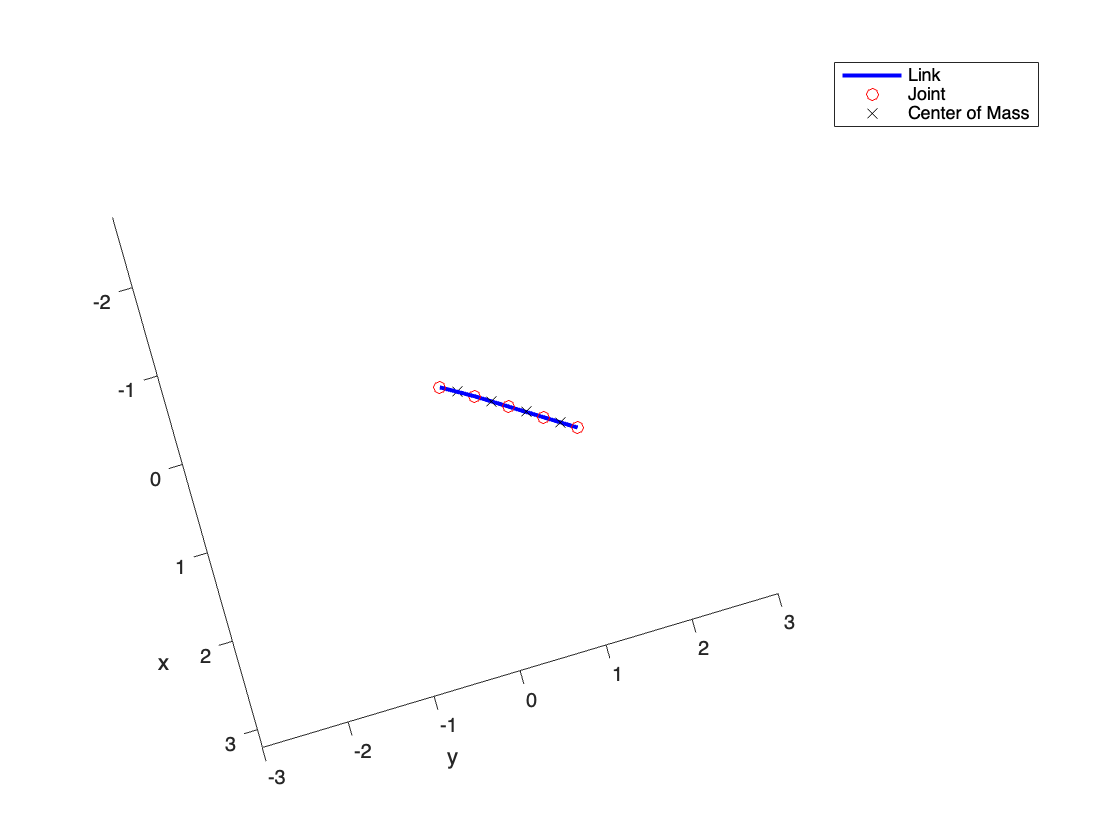

max_axis=3;
figure('color',[1 1 1]); set(gca, 'XLim', [-max_axis max_axis], 'YLim', [-max_axis max_axis], 'ZLim', [-max_axis max_axis]); view(43,24); hold on;
h1 = plot3(0,0,0, 'b', 'linewidth',2);   % The link
h2 = plot3(0,0,0, 'or');  % The joint/end-effector
h3 = plot3(0,0,0, 'xk');  % The center of mass
xlabel('x')
ylabel('y')
zlabel('z')
legend('Link', 'Joint', 'Center of Mass')
EE = zeros(3, N_DOFS+1);
COM = zeros(3, N_DOFS);    

for k = 1 : length(zSol)
    x0=xGSol(k); y0=yGSol(k); z0=zGSol(k);
    T0=trvec2tform([x0,y0,z0]);

    T0(1:3,1:3)=rotation321(phiSol(k), thetaSol(k), psiSol(k))
    for i = 1 : 1 : N_DOFS
        T = simplified_transformation(i, T0, dh, qc(k,:));
        EE(:,i+1) = T(1:3,4);
        COM(:,i) = EE(:,i+1) + T(1:3,1:3) * rb.r(:,i);
    end
    
    % Draw the robot
    set(h1, 'XData', EE(1, :), 'YData', EE(2, :),'ZData', EE(3, :));
    set(h2, 'XData', EE(1, :), 'YData', EE(2, :),'ZData', EE(3, :));
    set(h3, 'XData', COM(1, :), 'YData', COM(2, :),'ZData', COM(3, :));
    drawnow;
end

function R=rotation321(phi, thetaa, psi)
R_x=[1 0 0;
    0 cos(phi) -sin(phi);
    0 sin(phi) cos(phi)];
R_y=[cos(thetaa) 0 sin(thetaa);
    0 1 0;
    -sin(thetaa) 0 cos(thetaa)];
R_z=[cos(psi) -sin(psi) 0;
    sin(psi) cos(psi) 0;
    0 0 1];
R=R_z*R_y*R_x;
end
function  T = simplified_transformation(n, T0, dh, qc)
    % input dh as struct
    % Transformation from base joint to another joint
    % Removed prismatic joints, angle offset
    T = T0;
    
    for i = 1 : n
        dh.theta(i) = qc(i);
        
        ct = cos(dh.theta(i));
        st = sin(dh.theta(i));
        ca = cos(dh.alpha(i));
        sa = sin(dh.alpha(i));
        
        T = T * [ ct    -st*ca   st*sa     dh.a(i)*ct ; ...
                  st    ct*ca    -ct*sa    dh.a(i)*st ; ...
                  0     sa       ca        dh.d(i)    ; ...
                  0     0        0         1          ];
    end
end